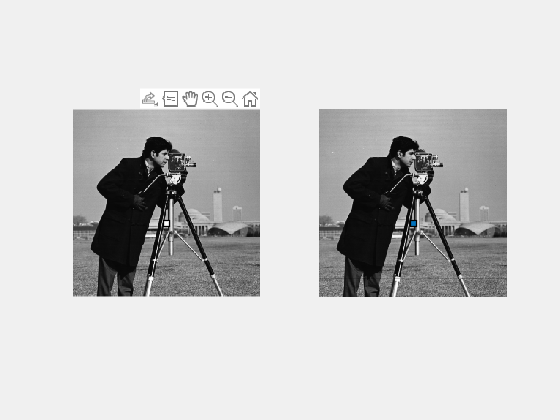

% Read images
I = imread('cameraman.tif');
I2 = imread('cameraman.tif');

% plot image 1 & draw a rectangular ROI on images
subplot(1,2,1); imshow(I);
roi = drawrectangle('LineWidth',2,'Color','white');
subplot(1,2,2); imshow(I2);
roi2 = drawrectangle(gca,'Position',roi.Position);


% set up listeners for ROI moving events
addlistener(roi,'MovingROI',@(r1,evt) allevents(r1,evt,roi2));
% addlistener(roi,'ROIMoved',@(r1,evt) allevents(r1,evt,roi2));

% allevents callback function displays the previous position & the current position of the ROI

function allevents(roi1,evt,roi2)
    evname = evt.EventName;
    roi2.Position = roi1.Position;
    switch(evname)
        case{'MovingROI'}
            disp(['ROI moving previous position: ' mat2str(evt.PreviousPosition)]);
            disp(['ROI moving current position: ' mat2str(evt.CurrentPosition)]);
        case{'ROIMoved'}
            disp(['ROI moved previous position: ' mat2str(evt.PreviousPosition)]);
            disp(['ROI moved current position: ' mat2str(evt.CurrentPosition)]);
    end
end